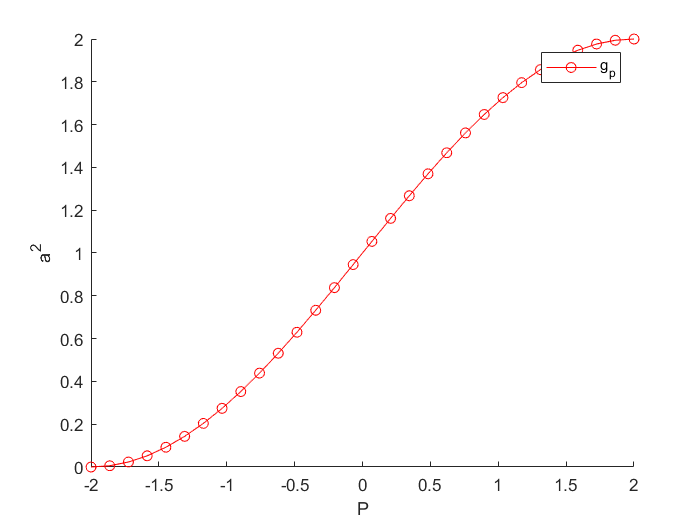

p = linspace(-2,2,30);
g_p = 1+sin((pi/4).*p);
figure;
hold on;
plot(p,g_p, 'ro-');
xlabel ('P');
ylabel ('a^2');
array = "g_p";
valores = [];
valores  = [valores array];
legend(valores);


%parse p to a vector column
p = p(:);
m = length(p);
%Inicialización de los valores aleatorios
W_1 = -1 + (1+1)*rand(2,1);
b_1 = -1 + (1+1)*rand(2,1);
W_2 = -1 + (1+1)*rand(1,2);
b_2 = -1 + (1+1)*rand(1,1);
alpha =0.01;
a_0 = p;
a_1 = zeros(m,2);
a_2 = zeros(m,1);
error = 1;
Eepoch = 0.01;
maxEpoch = 20;

for e = i :maxEpoch
    %Propagación hacia adelante
    for i = 1 : m
        a_1(i,:) = logsig(W_1*p(i,:)' +b_1);
        a_2(i,:) = purelin(W_2*a_1(i,:)' +b_2);   
    end
    a = a_2;
    %Error
    error = sum(a - p).^2/m;
    %verificación del error
    disp(error);
    if error>Eepoch
        for i = 1:m
           
            f_n_1 = eye(2).*(a_1(i)');
            disp( f_n_1)
            s_2 = -2.*(1).*(g_p(i)-a(i));
            s_1 = (f_n_1*W_2')*s_2;% 2x2 - 1x2 - 1x1
            W_2 = W_2 - alpha.*(s_2*a_1(i,:));
            b_2 = b_2 - alpha.*(s_2);
            W_1 = W_1 - alpha.*(s_1*a_0(i));
            b_1 = b_1 - alpha.*s_1;
        end
    else
        disp("La red convergió");
        break;
    end
    %Backpropagation
    
    
    
end

    4.9599



    0.9385         0
         0    0.9385



    0.9307         0
         0    0.9307

    0.9219         0
         0    0.9219

    0.9122         0
         0    0.9122

    0.9014         0
         0    0.9014

    0.8894         0
         0    0.8894

    0.8762         0
         0    0.8762

    0.8616         0
         0    0.8616

    0.8456         0
         0    0.8456

    0.8281         0
         0    0.8281

    0.8091         0
         0    0.8091

    0.7886         0
         0    0.7886

    0.7664         0
         0    0.7664

    0.7427         0
         0    0.7427

    0.7175         0
         0    0.7175

    0.6908         0
         0    0.6908

    0.6628         0
         0    0.6628

    0.6336         0
         0    0.6336

    0.6034         0
         0    0.6034

    0.5724         0
         0    0.5724

    0.5408         0
         0    0.5408

    0.5089         0
         0    0.5089

    0.4769         0
         0    0.4769

    0.4451         0
         0    0.4451

    0.4137 

   32.9899



    0.9264         0
         0    0.9264

    0.9186         0
         0    0.9186

    0.9101         0
         0    0.9101

    0.9008         0
         0    0.9008

    0.8906         0
         0    0.8906

    0.8795         0
         0    0.8795

    0.8674         0
         0    0.8674

    0.8544         0
         0    0.8544

    0.8403         0
         0    0.8403

    0.8251         0
         0    0.8251

    0.8087         0
         0    0.8087

    0.7913         0
         0    0.7913

    0.7727         0
         0    0.7727

    0.7530         0
         0    0.7530

    0.7321         0
         0    0.7321

    0.7102         0
         0    0.7102

    0.6872         0
         0    0.6872

    0.6633         0
         0    0.6633

    0.6385         0
         0    0.6385

    0.6130         0
         0    0.6130

    0.5868         0
         0    0.5868

    0.5601         0
         0    0.5601

    0.5331         0
         0    0.5331

    0.5058 

   28.7325



    0.8912         0
         0    0.8912

    0.8829         0
         0    0.8829

    0.8740         0
         0    0.8740

    0.8645         0
         0    0.8645

    0.8544         0
         0    0.8544

    0.8437         0
         0    0.8437

    0.8324         0
         0    0.8324

    0.8204         0
         0    0.8204

    0.8078         0
         0    0.8078

    0.7945         0
         0    0.7945

    0.7805         0
         0    0.7805

    0.7659         0
         0    0.7659

    0.7506         0
         0    0.7506

    0.7346         0
         0    0.7346

    0.7180         0
         0    0.7180

    0.7008         0
         0    0.7008

    0.6830         0
         0    0.6830

    0.6646         0
         0    0.6646

    0.6458         0
         0    0.6458

    0.6265         0
         0    0.6265

    0.6067         0
         0    0.6067

    0.5866         0
         0    0.5866

    0.5663         0
         0    0.5663

    0.5456 

   30.5109



    0.8582         0
         0    0.8582

    0.8502         0
         0    0.8502

    0.8419         0
         0    0.8419

    0.8331         0
         0    0.8331

    0.8240         0
         0    0.8240

    0.8145         0
         0    0.8145

    0.8046         0
         0    0.8046

    0.7943         0
         0    0.7943

    0.7836         0
         0    0.7836

    0.7725         0
         0    0.7725

    0.7610         0
         0    0.7610

    0.7492         0
         0    0.7492

    0.7369         0
         0    0.7369

    0.7243         0
         0    0.7243

    0.7113         0
         0    0.7113

    0.6979         0
         0    0.6979

    0.6842         0
         0    0.6842

    0.6701         0
         0    0.6701

    0.6558         0
         0    0.6558

    0.6412         0
         0    0.6412

    0.6263         0
         0    0.6263

    0.6111         0
         0    0.6111

    0.5957         0
         0    0.5957

    0.5802 

   30.8875



    0.8251         0
         0    0.8251

    0.8180         0
         0    0.8180

    0.8106         0
         0    0.8106

    0.8031         0
         0    0.8031

    0.7954         0
         0    0.7954

    0.7874         0
         0    0.7874

    0.7792         0
         0    0.7792

    0.7707         0
         0    0.7707

    0.7621         0
         0    0.7621

    0.7532         0
         0    0.7532

    0.7441         0
         0    0.7441

    0.7348         0
         0    0.7348

    0.7252         0
         0    0.7252

    0.7155         0
         0    0.7155

    0.7056         0
         0    0.7056

    0.6954         0
         0    0.6954

    0.6851         0
         0    0.6851

    0.6745         0
         0    0.6745

    0.6638         0
         0    0.6638

    0.6530         0
         0    0.6530

    0.6419         0
         0    0.6419

    0.6307         0
         0    0.6307

    0.6194         0
         0    0.6194

    0.6079 

   31.2234



    0.7941         0
         0    0.7941

    0.7882         0
         0    0.7882

    0.7823         0
         0    0.7823

    0.7762         0
         0    0.7762

    0.7699         0
         0    0.7699

    0.7636         0
         0    0.7636

    0.7571         0
         0    0.7571

    0.7506         0
         0    0.7506

    0.7439         0
         0    0.7439

    0.7370         0
         0    0.7370

    0.7301         0
         0    0.7301

    0.7231         0
         0    0.7231

    0.7159         0
         0    0.7159

    0.7087         0
         0    0.7087

    0.7013         0
         0    0.7013

    0.6938         0
         0    0.6938

    0.6862         0
         0    0.6862

    0.6785         0
         0    0.6785

    0.6708         0
         0    0.6708

    0.6629         0
         0    0.6629

    0.6549         0
         0    0.6549

    0.6469         0
         0    0.6469

    0.6387         0
         0    0.6387

    0.6305 

   31.3583



    0.7659         0
         0    0.7659

    0.7614         0
         0    0.7614

    0.7569         0
         0    0.7569

    0.7523         0
         0    0.7523

    0.7476         0
         0    0.7476

    0.7429         0
         0    0.7429

    0.7381         0
         0    0.7381

    0.7333         0
         0    0.7333

    0.7284         0
         0    0.7284

    0.7235         0
         0    0.7235

    0.7185         0
         0    0.7185

    0.7134         0
         0    0.7134

    0.7083         0
         0    0.7083

    0.7032         0
         0    0.7032

    0.6980         0
         0    0.6980

    0.6927         0
         0    0.6927

    0.6874         0
         0    0.6874

    0.6820         0
         0    0.6820

    0.6766         0
         0    0.6766

    0.6712         0
         0    0.6712

    0.6656         0
         0    0.6656

    0.6601         0
         0    0.6601

    0.6545         0
         0    0.6545

    0.6489 

   31.3863



    0.7407         0
         0    0.7407

    0.7376         0
         0    0.7376

    0.7345         0
         0    0.7345

    0.7314         0
         0    0.7314

    0.7282         0
         0    0.7282

    0.7250         0
         0    0.7250

    0.7218         0
         0    0.7218

    0.7186         0
         0    0.7186

    0.7153         0
         0    0.7153

    0.7120         0
         0    0.7120

    0.7087         0
         0    0.7087

    0.7054         0
         0    0.7054

    0.7021         0
         0    0.7021

    0.6987         0
         0    0.6987

    0.6953         0
         0    0.6953

    0.6919         0
         0    0.6919

    0.6885         0
         0    0.6885

    0.6851         0
         0    0.6851

    0.6816         0
         0    0.6816

    0.6781         0
         0    0.6781

    0.6746         0
         0    0.6746

    0.6711         0
         0    0.6711

    0.6675         0
         0    0.6675

    0.6639 

   31.3447



    0.7184         0
         0    0.7184

    0.7166         0
         0    0.7166

    0.7149         0
         0    0.7149

    0.7131         0
         0    0.7131

    0.7113         0
         0    0.7113

    0.7096         0
         0    0.7096

    0.7078         0
         0    0.7078

    0.7060         0
         0    0.7060

    0.7042         0
         0    0.7042

    0.7024         0
         0    0.7024

    0.7006         0
         0    0.7006

    0.6987         0
         0    0.6987

    0.6969         0
         0    0.6969

    0.6951         0
         0    0.6951

    0.6933         0
         0    0.6933

    0.6914         0
         0    0.6914

    0.6896         0
         0    0.6896

    0.6877         0
         0    0.6877

    0.6858         0
         0    0.6858

    0.6840         0
         0    0.6840

    0.6821         0
         0    0.6821

    0.6802         0
         0    0.6802

    0.6783         0
         0    0.6783

    0.6764 

   31.2644



    0.6988         0
         0    0.6988

    0.6982         0
         0    0.6982

    0.6977         0
         0    0.6977

    0.6972         0
         0    0.6972

    0.6967         0
         0    0.6967

    0.6962         0
         0    0.6962

    0.6957         0
         0    0.6957

    0.6952         0
         0    0.6952

    0.6947         0
         0    0.6947

    0.6942         0
         0    0.6942

    0.6936         0
         0    0.6936

    0.6931         0
         0    0.6931

    0.6926         0
         0    0.6926

    0.6921         0
         0    0.6921

    0.6916         0
         0    0.6916

    0.6911         0
         0    0.6911

    0.6905         0
         0    0.6905

    0.6900         0
         0    0.6900

    0.6895         0
         0    0.6895

    0.6890         0
         0    0.6890

    0.6885         0
         0    0.6885

    0.6880         0
         0    0.6880

    0.6874         0
         0    0.6874

    0.6869 

   31.1644



    0.6815         0
         0    0.6815

    0.6821         0
         0    0.6821

    0.6827         0
         0    0.6827

    0.6834         0
         0    0.6834

    0.6840         0
         0    0.6840

    0.6846         0
         0    0.6846

    0.6852         0
         0    0.6852

    0.6859         0
         0    0.6859

    0.6865         0
         0    0.6865

    0.6871         0
         0    0.6871

    0.6877         0
         0    0.6877

    0.6884         0
         0    0.6884

    0.6890         0
         0    0.6890

    0.6896         0
         0    0.6896

    0.6902         0
         0    0.6902

    0.6908         0
         0    0.6908

    0.6915         0
         0    0.6915

    0.6921         0
         0    0.6921

    0.6927         0
         0    0.6927

    0.6933         0
         0    0.6933

    0.6939         0
         0    0.6939

    0.6945         0
         0    0.6945

    0.6952         0
         0    0.6952

    0.6958 

   31.0571



    0.6662         0
         0    0.6662

    0.6679         0
         0    0.6679

    0.6696         0
         0    0.6696

    0.6712         0
         0    0.6712

    0.6729         0
         0    0.6729

    0.6745         0
         0    0.6745

    0.6761         0
         0    0.6761

    0.6778         0
         0    0.6778

    0.6794         0
         0    0.6794

    0.6810         0
         0    0.6810

    0.6827         0
         0    0.6827

    0.6843         0
         0    0.6843

    0.6859         0
         0    0.6859

    0.6875         0
         0    0.6875

    0.6891         0
         0    0.6891

    0.6907         0
         0    0.6907

    0.6923         0
         0    0.6923

    0.6939         0
         0    0.6939

    0.6955         0
         0    0.6955

    0.6971         0
         0    0.6971

    0.6986         0
         0    0.6986

    0.7002         0
         0    0.7002

    0.7018         0
         0    0.7018

    0.7033 

   30.9498



    0.6528         0
         0    0.6528

    0.6554         0
         0    0.6554

    0.6580         0
         0    0.6580

    0.6605         0
         0    0.6605

    0.6631         0
         0    0.6631

    0.6656         0
         0    0.6656

    0.6682         0
         0    0.6682

    0.6707         0
         0    0.6707

    0.6733         0
         0    0.6733

    0.6758         0
         0    0.6758

    0.6783         0
         0    0.6783

    0.6808         0
         0    0.6808

    0.6833         0
         0    0.6833

    0.6857         0
         0    0.6857

    0.6882         0
         0    0.6882

    0.6906         0
         0    0.6906

    0.6931         0
         0    0.6931

    0.6955         0
         0    0.6955

    0.6979         0
         0    0.6979

    0.7003         0
         0    0.7003

    0.7027         0
         0    0.7027

    0.7051         0
         0    0.7051

    0.7075         0
         0    0.7075

    0.7099 

   30.8468



    0.6409         0
         0    0.6409

    0.6443         0
         0    0.6443

    0.6477         0
         0    0.6477

    0.6511         0
         0    0.6511

    0.6545         0
         0    0.6545

    0.6579         0
         0    0.6579

    0.6612         0
         0    0.6612

    0.6645         0
         0    0.6645

    0.6679         0
         0    0.6679

    0.6712         0
         0    0.6712

    0.6745         0
         0    0.6745

    0.6777         0
         0    0.6777

    0.6810         0
         0    0.6810

    0.6842         0
         0    0.6842

    0.6874         0
         0    0.6874

    0.6906         0
         0    0.6906

    0.6938         0
         0    0.6938

    0.6970         0
         0    0.6970

    0.7001         0
         0    0.7001

    0.7032         0
         0    0.7032

    0.7064         0
         0    0.7064

    0.7094         0
         0    0.7094

    0.7125         0
         0    0.7125

    0.7156 

   30.7504



    0.6302         0
         0    0.6302

    0.6344         0
         0    0.6344

    0.6386         0
         0    0.6386

    0.6427         0
         0    0.6427

    0.6469         0
         0    0.6469

    0.6510         0
         0    0.6510

    0.6550         0
         0    0.6550

    0.6591         0
         0    0.6591

    0.6631         0
         0    0.6631

    0.6671         0
         0    0.6671

    0.6711         0
         0    0.6711

    0.6751         0
         0    0.6751

    0.6790         0
         0    0.6790

    0.6829         0
         0    0.6829

    0.6868         0
         0    0.6868

    0.6907         0
         0    0.6907

    0.6945         0
         0    0.6945

    0.6983         0
         0    0.6983

    0.7021         0
         0    0.7021

    0.7058         0
         0    0.7058

    0.7095         0
         0    0.7095

    0.7132         0
         0    0.7132

    0.7169         0
         0    0.7169

    0.7205 

   30.6617



    0.6208         0
         0    0.6208

    0.6256         0
         0    0.6256

    0.6305         0
         0    0.6305

    0.6353         0
         0    0.6353

    0.6401         0
         0    0.6401

    0.6448         0
         0    0.6448

    0.6495         0
         0    0.6495

    0.6542         0
         0    0.6542

    0.6589         0
         0    0.6589

    0.6636         0
         0    0.6636

    0.6682         0
         0    0.6682

    0.6727         0
         0    0.6727

    0.6773         0
         0    0.6773

    0.6818         0
         0    0.6818

    0.6863         0
         0    0.6863

    0.6907         0
         0    0.6907

    0.6951         0
         0    0.6951

    0.6995         0
         0    0.6995

    0.7038         0
         0    0.7038

    0.7081         0
         0    0.7081

    0.7124         0
         0    0.7124

    0.7166         0
         0    0.7166

    0.7208         0
         0    0.7208

    0.7250 

   30.5811



    0.6122         0
         0    0.6122

    0.6177         0
         0    0.6177

    0.6232         0
         0    0.6232

    0.6286         0
         0    0.6286

    0.6340         0
         0    0.6340

    0.6393         0
         0    0.6393

    0.6446         0
         0    0.6446

    0.6499         0
         0    0.6499

    0.6552         0
         0    0.6552

    0.6604         0
         0    0.6604

    0.6655         0
         0    0.6655

    0.6707         0
         0    0.6707

    0.6758         0
         0    0.6758

    0.6808         0
         0    0.6808

    0.6858         0
         0    0.6858

    0.6908         0
         0    0.6908

    0.6957         0
         0    0.6957

    0.7006         0
         0    0.7006

    0.7054         0
         0    0.7054

    0.7102         0
         0    0.7102

    0.7150         0
         0    0.7150

    0.7196         0
         0    0.7196

    0.7243         0
         0    0.7243

    0.7289 

   30.5086



    0.6045         0
         0    0.6045

    0.6106         0
         0    0.6106

    0.6166         0
         0    0.6166

    0.6225         0
         0    0.6225

    0.6285         0
         0    0.6285

    0.6344         0
         0    0.6344

    0.6402         0
         0    0.6402

    0.6460         0
         0    0.6460

    0.6518         0
         0    0.6518

    0.6575         0
         0    0.6575

    0.6632         0
         0    0.6632

    0.6689         0
         0    0.6689

    0.6744         0
         0    0.6744

    0.6800         0
         0    0.6800

    0.6855         0
         0    0.6855

    0.6909         0
         0    0.6909

    0.6963         0
         0    0.6963

    0.7016         0
         0    0.7016

    0.7069         0
         0    0.7069

    0.7121         0
         0    0.7121

    0.7173         0
         0    0.7173

    0.7224         0
         0    0.7224

    0.7274         0
         0    0.7274

    0.7324 

   30.4437



    0.5975         0
         0    0.5975

    0.6041         0
         0    0.6041

    0.6106         0
         0    0.6106

    0.6171         0
         0    0.6171

    0.6235         0
         0    0.6235

    0.6299         0
         0    0.6299

    0.6362         0
         0    0.6362

    0.6425         0
         0    0.6425

    0.6488         0
         0    0.6488

    0.6550         0
         0    0.6550

    0.6611         0
         0    0.6611

    0.6672         0
         0    0.6672

    0.6732         0
         0    0.6732

    0.6792         0
         0    0.6792

    0.6851         0
         0    0.6851

    0.6910         0
         0    0.6910

    0.6968         0
         0    0.6968

    0.7026         0
         0    0.7026

    0.7082         0
         0    0.7082

    0.7138         0
         0    0.7138

    0.7194         0
         0    0.7194

    0.7249         0
         0    0.7249

    0.7303         0
         0    0.7303

    0.7356 

   30.3859



    0.5911         0
         0    0.5911

    0.5982         0
         0    0.5982

    0.6051         0
         0    0.6051

    0.6121         0
         0    0.6121

    0.6190         0
         0    0.6190

    0.6258         0
         0    0.6258

    0.6326         0
         0    0.6326

    0.6393         0
         0    0.6393

    0.6460         0
         0    0.6460

    0.6527         0
         0    0.6527

    0.6592         0
         0    0.6592

    0.6657         0
         0    0.6657

    0.6722         0
         0    0.6722

    0.6786         0
         0    0.6786

    0.6849         0
         0    0.6849

    0.6911         0
         0    0.6911

    0.6973         0
         0    0.6973

    0.7034         0
         0    0.7034

    0.7095         0
         0    0.7095

    0.7154         0
         0    0.7154

    0.7213         0
         0    0.7213

    0.7271         0
         0    0.7271

    0.7329         0
         0    0.7329

    0.7385 